## Turn angle before turn vs. Run speed

by Ercag

November 2021 

clearvars;
close all; 


## Define Export Path for figures

ExpPath = 'C:\Users\ercagp\Box\Research\VibrioFischeri_Project\Data\AngularAnalysis\Correlations';

## Call the run reverse analysis files

MainPath = 'C:\Users\ercagp\Documents\Rowland_Data\RunReverseAnalysis\RunReverse_Data';
StrainLabels = {'KMT53'};
Lambda = 0.5;

## Input parameters 

%Acquisition and ADMM parameter
fps = 30; %Hz
Lambda = 0.5; 

%Time stamp for the PNG/PDF files
Stamp =  ['[' char(datetime('now','Format','yyyyMMdd')) ']'];

%RegExp Keys
RegKeyROI = 'ROI[_]\d';
RegKeyVD = ['(?<=Data' filesep filesep ')\d*'];

% Define Histogram Parameters
PltPara.Normalization = 'PDF';



## Plot 2D-histogram of Turn angle vs. mean run speed before & after

Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {[      50]}    {2312×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {[      50]}    {2312×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {[      50]}    {2312×2 cell  }
    {[      50]}    {2142×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {[      50]}    {2312×2 cell  }
    {[      50]}    {2142×2 cell  }
    {0×0 double}    {   0×0 double}
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {[      50]}    {2312×2 cell  }
    {[      50]}    {2142×2 cell  }
    {[      75]}    {2706×2 cell  }
    {0×0 double}    {   0×0 double}


After = 46×2 cell array
    {[     100]}    {2630×2 cell  }
    {[     100]}    {2416×2 cell  }
    {[      25]}    {2197×2 cell  }
    {[      25]}    {2303×2 cell  }
    {[      50]}    {3063×2 cell  }
    {[      50]}    {2531×2 cell  }
    {[      75]}    {2125×2 cell  }
    {[      75]}    {2431×2 cell  }
    {[     100]}    {1814×2 cell  }
    {[     100]}    {2075×2 cell  }
    {[      25]}    {2328×2 cell  }
    {[      25]}    {1633×2 cell  }
    {[      50]}    {2312×2 cell  }
    {[      50]}    {2142×2 cell  }
    {[      75]}    {2706×2 cell  }
    {0×0 double}    {   0×0 double}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


Before = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


After = 46×2 cell array
    {[100]}    {2630×2 cell}
    {[100]}    {2416×2 cell}
    {[ 25]}    {2197×2 cell}
    {[ 25]}    {2303×2 cell}
    {[ 50]}    {3063×2 cell}
    {[ 50]}    {2531×2 cell}
    {[ 75]}    {2125×2 cell}
    {[ 75]}    {2431×2 cell}
    {[100]}    {1814×2 cell}
    {[100]}    {2075×2 cell}
    {[ 25]}    {2328×2 cell}
    {[ 25]}    {1633×2 cell}
    {[ 50]}    {2312×2 cell}
    {[ 50]}    {2142×2 cell}
    {[ 75]}    {2706×2 cell}
    {[ 75]}    {2164×2 cell}


ExpFile = struct with fields:
    Strain: 'KMT53'


ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'


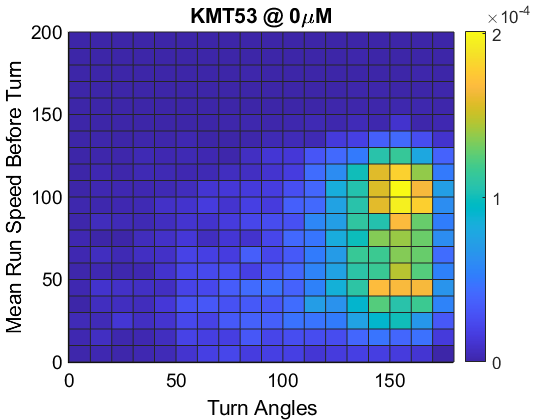

ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '0'


ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '0'


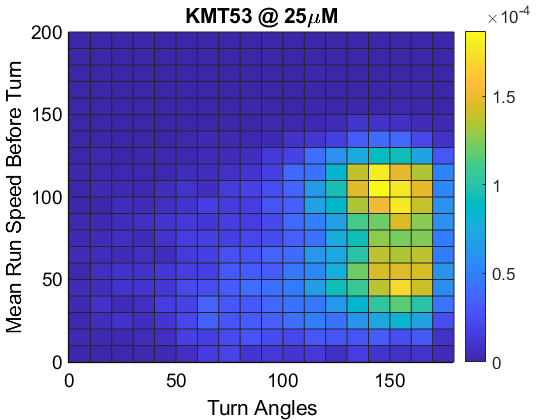

ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '25'


ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '25'


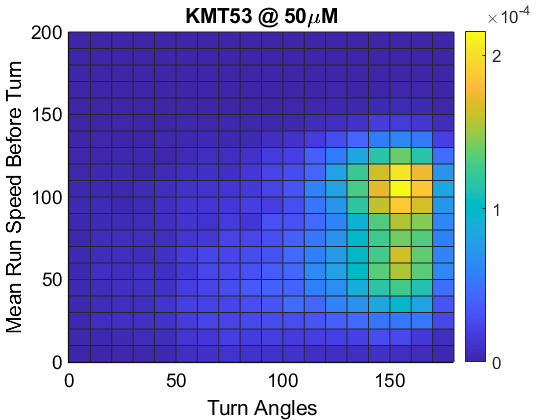

ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '50'


ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '50'


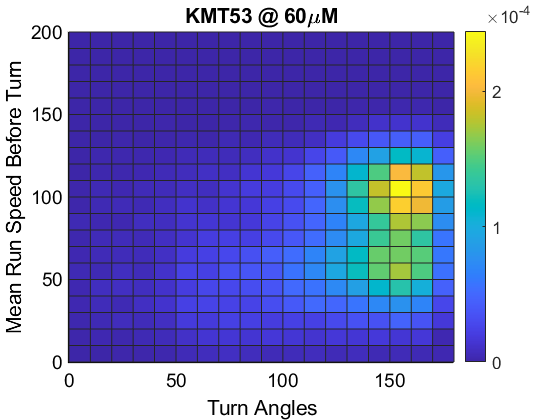

ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '60'


ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '60'


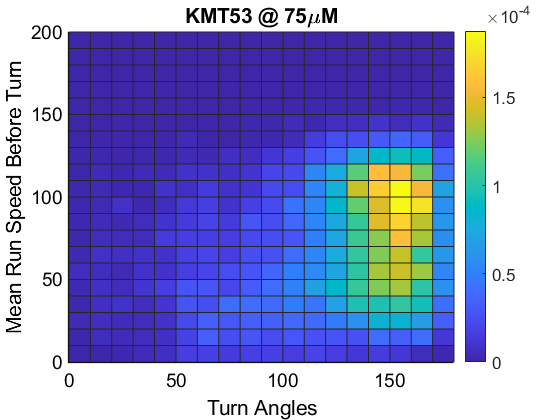

ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '75'


ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '75'


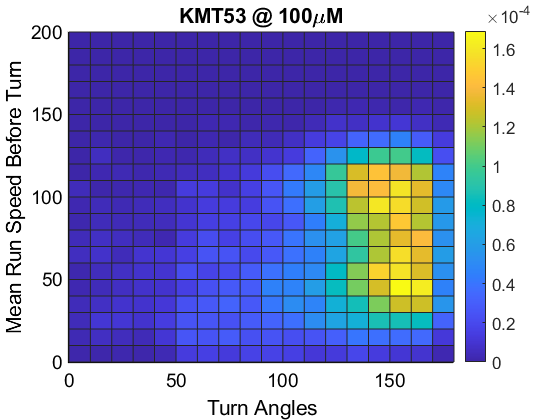

ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '100'


ExpFile = struct with fields:
       Strain: 'KMT53'
    PlotLabel: 'TurnAngle_MeanSpeedBeforeTurn'
         IPTG: '100'


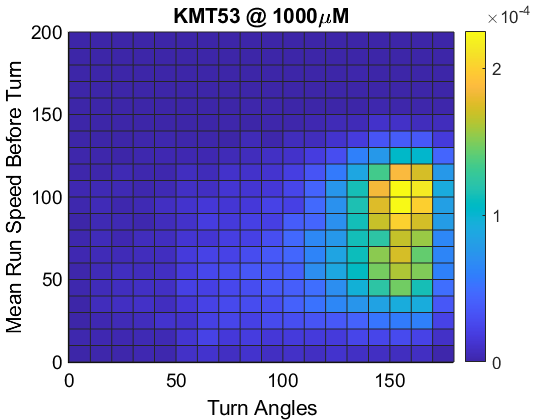

for j = 1:length(StrainLabels) 
    %Find .mat files
    Files = callResultsv2(MainPath, StrainLabels{j},Lambda);
    %Preallocate
    IPTG = zeros(length(Files),1);
    TurnAngle = cell(length(Files),2);
    Runs = cell(length(Files),2); 
    Before = cell(length(Files),2); 
    After = cell(length(Files),2); 
    
    for i = 1:length(Files)
        %Call the run-reverse file 
        load(Files{i});
        %Correct the wrong IPTG label 
        IPTG(i) = RunReverse.Info.IPTG;
        if IPTG(i) == 1
           IPTG(i) = IPTG(i)*1000;
        end
        
        %Store IPTG value
        TurnAngle{i,1} = IPTG(i);
        Runs{i,1} = IPTG(i);
        Before{i,1} = IPTG(i);
        After{i,1} = IPTG(i);
        
        TurnAngle{i,2} = Results.Ang(:,3); %note: all turn angles are already filtered
        Runs{i,2} = RunBreakDownv6(Speeds,Results.T,fps); %!!! Complete + Incomplete Runs!!! 
        
        [Before{i,2}, After{i,2}] = test_sep(Runs{i,2},TurnAngle{i,2})
    end
    %Match the data belonging to the same IPTG value
    %Ang_Combined = matchrepeat(TurnAngle(:,1),TurnAngle(:,2)); 
    Before_Cmb = matchrepeat(Before(:,1),Before(:,2)); 
    After_Cmb = matchrepeat(After(:,1),After(:,2)); 

    for k = 1:size(Before_Cmb,1)
        
        %Replace all empty ROW vectors by COLUMN vectors to 
        % be able to run CELL2MAT command
        Before_Cmb{k,2} = replace_empty(Before_Cmb{k,2});
        After_Cmb{k,2} = replace_empty(After_Cmb{k,2});
        
        Test_BFR = cell2mat(Before_Cmb{k,2});
        
        hf{k} = figure(k);
        Plot.X = Test_BFR(:,1);
        Plot.Y = Test_BFR(:,2);
        Plot.XTitle = 'Turn Angles';
        Plot.YTitle = 'Mean Run Speed Before Turn'; 
        Plot.Title = [StrainLabels{j} ' @ ' num2str(Before_Cmb{k,1}) '\mu{}M']; 
        %Define X- and Y-Edges
        Plot.XEdges = 0:10:180; % Turn angles
        Plot.YEdges = 0:10:200; % Mean speed before a turn 
        hist_BFR{k} = plotHist(hf{k},Plot); 
        
        ExpFile.Strain = StrainLabels{j}
        ExpFile.PlotLabel = 'TurnAngle_MeanSpeedBeforeTurn'
        ExpFile.IPTG = num2str(Before_Cmb{k,1});
        ExpFig(hf{k},ExpFile,ExpPath)
    end


end

## Functions

function [Bfr, Aft] = test_sep(Run,Ang) 
         Bfr = cell(size(Run,1),2);
         Aft = cell(size(Run,1),2);
         for i = 1:size(Run,1)
             if isempty(Run{i,2})
                MeanSpeeds = double.empty(0,1);
             else
                MeanSpeeds = [Run{i,2}(:,2)];
             end
                          
             TurnAngles = [Ang{i}]; 
             %1st column: Angles
             Bfr{i,1} = TurnAngles;
             Aft{i,1} = TurnAngles;
             %2nd column: Speeds
             Bfr{i,2} = MeanSpeeds(1:end-1);
             Aft{i,2} = MeanSpeeds(2:end);
         end
         
end

function x = replace_empty(x)
         I = cellfun(@isempty, x);
         x(I(:,1),1) = cellfun(@rep,x(I(:,1)),'UniformOutput',0);
         x(I(:,2),2) = cellfun(@rep,x(I(:,2)),'UniformOutput',0);
         %I fucking hate this type of pointers!                  
    function  y = rep(~)
              y = double.empty(0,1);
    end
end


function Hist = plotHist(h_Fig,P)
         figure(h_Fig)
         X = P.X; 
         Y = P.Y; 
         XEdges = P.XEdges;
         YEdges = P.YEdges;
         XTitle = P.XTitle;
         YTitle = P.YTitle; 
         Title = P.Title; 
        
         Hist = histogram2(X,Y,XEdges,YEdges,...
                          'DisplayStyle','tile','ShowEmptyBins','on','Normalization','PDF');        
         colorbar; 
         title(Title);
         xlabel(XTitle);
         ylabel(YTitle);
         ErcagGraphics
end

function ExpFig(h_Fig,S,ExpPath)
         %Time stamp for the PNG/PDF files
         Stamp =  ['[' char(datetime('now','Format','yyyyMMdd')) ']'];
                        
            
         if ~exist(ExpPath,'dir')
            mkdir(ExpPath)
         end   
         
         FullFileName = [Stamp S.Strain '_' S.PlotLabel '_IPTG_' S.IPTG 'uM'];
         
         printfig(h_Fig,fullfile(ExpPath,FullFileName),'-dpng');
         printfig(h_Fig,fullfile(ExpPath,FullFileName),'-dpdf');
         savefig(h_Fig,fullfile(ExpPath,FullFileName));
end
